- Utilice las funciones de RVC para construir un modelo en alambres. 

    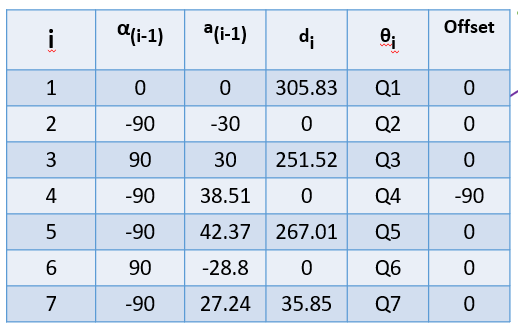

%%  Definicion parametros variables de las articulaciones
q1=0; 
q2=0; 
q3=0;
q4=0;
q5=0;
q6=0;
q7=0;

% Creacion del modelo geométrico con la función Link
L(1) = Link('revolute','alpha', 0,      'a', 0,   'd',305.83,   'offset', 0,   'modified', 'qlim',[-337*pi/360 337*pi/360]);
L(2) = Link('revolute','alpha', -pi/2,  'a', -30,    'd',0,   'offset', 0,   'modified', 'qlim',[-287*pi/360 29*pi/120]);
L(3) = Link('revolute','alpha', pi/2,      'a', 30, 'd',251.52,   'offset', 0,   'modified', 'qlim',[-337*pi/360 337*pi/360]);
L(4) = Link('revolute','alpha', -pi/2,      'a', 38.51, 'd',0,   'offset', -pi/2,   'modified', 'qlim',[-247*pi/360 4*pi/9]);
L(5) = Link('revolute','alpha', -pi/2,      'a', 42.37,   'd',267.01,   'offset', 0,   'modified', 'qlim',[-29*pi/18 29*pi/18]);
L(6) = Link('revolute','alpha', pi/2,      'a', -28.8,   'd',0,   'offset', 0,   'modified', 'qlim',[-22*pi/45 23*pi/30]);
L(7) = Link('revolute','alpha', -pi/2,      'a', 27.24,   'd',35.85,   'offset', 0,   'modified', 'qlim',[-229*pi/180 229*pi/180]);


R = SerialLink(L,'name','Robot URRPR DE 6 GDL')

 
R = 
 
Robot URRPR DE 6 GDL (7 axis, RRRRRRR, modDH, fastRNE)           
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|      305.8|          0|          0|          0|
|  2|         q2|          0|        -30|     -1.571|          0|
|  3|         q3|      251.5|         30|      1.571|          0|
|  4|         q4|          0|      38.51|     -1.571|     -1.571|
|  5|         q5|        267|      42.37|     -1.571|          0|
|  6|         q6|          0|      -28.8|      1.571|          0|
|  7|         q7|      35.85|      27.24|     -1.571|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
 

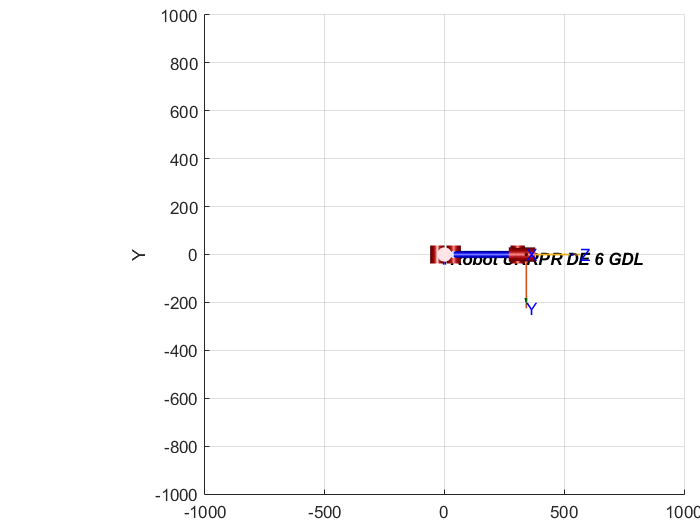


%Creación del espacio y generación del modelo de alambres
R.plot([q1 q2 q3 q4 q5 q6 q7],'workspace',[-300 300 -300 300 -300 300])
hold on
trplot(eye(4), 'width',2,'arrow')
axis([-1000 1000 -1000 1000 0 1000])
R.teach([q1 q2 q3 q4 q5 q6 q7])
hold off

####         Sección para la graficación del espacio de trabajo

R   %Sea R MTH obtenida de SeralLink
s = 2*pi;
step = 1;
hold on
for i = 0:step:s
    for j = 0:step:s
        for k = 0:step:s
            for m = 0:step:s
                for n=0:step:s
                    for p =0:step:s
                        
                        
                         endeffect = R.base*L(1).A(i)*L(2).A(j)*L(3).A(k)*L(4).A(m)*L(5).A(n)*L(6).A(p)*L(7).A(0);
                    position = endeffect(1:3,4);
                    plot3(position(1),position(2),position(3),'o');
                    
                    
                    end
                end
            end
        end
    end
end

 
R = 
 
Robot URRPR DE 6 GDL (7 axis, RRRRRRR, modDH, fastRNE)           
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|      305.8|          0|          0|          0|
|  2|         q2|          0|        -30|     -1.571|          0|
|  3|         q3|      251.5|         30|      1.571|          0|
|  4|         q4|          0|      38.51|     -1.571|     -1.571|
|  5|         q5|        267|      42.37|     -1.571|          0|
|  6|         q6|          0|      -28.8|      1.571|          0|
|  7|         q7|      35.85|      27.24|     -1.571|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
 

Error using rt2tr (line 42)
R and t must have the same number of rows

2. Utilice las funciones de RST para construir un modelo en alambres. 

% clear
% clc
%Creacion de un robor empleando Robotics System Toolbox

scala=1000;
%creacion cuerpo rigido 1
b1 = rigidBody('b1');
%creacion de las articulaciones 
j1 = rigidBodyJoint('j1','revolute');
j1.HomePosition = 0;
T01 = trvec2tform([0, 0, 305.83/scala]);
setFixedTransform(j1,T01);
b1.Joint = j1;
%creacion de un arbol rigido 
robot = rigidBodyTree;
%añadir el cuerpo al arbol
addBody(robot,b1,'base')


%creacion  cuerpo 2
b2 = rigidBody('b2');
j2 = rigidBodyJoint('j2','revolute');
j2.HomePosition = 0; % User defined
T12 = trvec2tform([-30/scala, 0, 0])*trotx(-pi/2); % User defined
setFixedTransform(j2,T12);
b2.Joint = j2;
addBody(robot,b2,'b1'); % Add body2 to body1

%creacion  cuerpo 3
b3 = rigidBody('b3');
j3 = rigidBodyJoint('j3','revolute');
j3.HomePosition = 0; % User defined
T23 = trvec2tform([30/scala, 0, 0])*trotx(pi/2)*trvec2tform([0, 0, 251.52/scala])*trotz(0); % User defined
setFixedTransform(j3,T23);
b3.Joint = j3;
addBody(robot,b3,'b2'); % Add body2 to body1

%creacion  cuerpo 4
b4 = rigidBody('b4');
j4 = rigidBodyJoint('j4','revolute');
j4.HomePosition = 0; % User defined
T34 = trvec2tform([38.51/scala, 0, 0])*trotx(-pi/2)*trvec2tform([0, 0, 0])*trotz(-pi/2); % User defined
setFixedTransform(j4,T34);
b4.Joint = j4;
addBody(robot,b4,'b3'); % Add body2 to body1

%creacion  cuerpo 5
b5 = rigidBody('b5');
j5 = rigidBodyJoint('j5','revolute');
j5.HomePosition = 0; % User defined
T45 = trvec2tform([42.37/scala, 0, 0])*trotx(-pi/2)*trvec2tform([0, 0, 267.01/scala])*trotz(0); % User defined
setFixedTransform(j5,T45);
b5.Joint = j5;
addBody(robot,b5,'b4'); % Add body2 to body1

%creacion  cuerpo 6
b6 = rigidBody('b6');
j6 = rigidBodyJoint('j6','revolute');
j6.HomePosition = 0; % User defined
T56 = trvec2tform([-28.8/scala, 0, 0])*trotx(pi/2)*trvec2tform([0, 0, 0])*trotz(0); % User defined
setFixedTransform(j6,T56);
b6.Joint = j6;
addBody(robot,b6,'b5'); % Add body2 to body1

%creacion  cuerpo 7
b7 = rigidBody('b7');
j7 = rigidBodyJoint('j7','revolute');
j7.HomePosition = 0; % User defined
T67 = trvec2tform([27.24/scala, 0, 0])*trotx(-pi/2)*trvec2tform([0, 0, 35.85/scala])*trotz(0); % User defined
setFixedTransform(j7,T67);
b7.Joint = j7;
addBody(robot,b7,'b6'); % Add body2 to body1



%%Efector final 
% bodyEndEffector = rigidBody('endeffector');
% tform5 = trvec2tform([0.5, 0, 0]); % User defined
% setFixedTransform(bodyEndEffector.Joint,tform5);
% addBody(robot,bodyEndEffector,'body4');

show(robot)
 